% Quintic Trajectory Planning in MATLAB
% Given parameters
q0 = 0;      % initial position
qf = 10;     % final position
v0 = 0;      % initial velocity
vf = 0;      % final velocity
a0 = 0;      % initial acceleration
af = 0;      % final acceleration
t_total = 10; % total time for the motion (seconds)

% Time vector
t = linspace(0, t_total, 1000);

% Coefficients for quintic polynomial
A = [1, 0, 0, 0, 0, 0;
     0, 1, 0, 0, 0, 0;
     0, 0, 2, 0, 0, 0;
     1, t_total, t_total^2, t_total^3, t_total^4, t_total^5;
     0, 1, 2*t_total, 3*t_total^2, 4*t_total^3, 5*t_total^4;
     0, 0, 2, 6*t_total, 12*t_total^2, 20*t_total^3];
b = [q0; v0; a0; qf; vf; af];
coeffs = A\b;

a0 = coeffs(1);
a1 = coeffs(2);
a2 = coeffs(3);
a3 = coeffs(4);
a4 = coeffs(5);
a5 = coeffs(6);

% Compute position, velocity, and acceleration
q = a0 + a1*t + a2*t.^2 + a3*t.^3 + a4*t.^4 + a5*t.^5;
v = a1 + 2*a2*t + 3*a3*t.^2 + 4*a4*t.^3 + 5*a5*t.^4;
a = 2*a2 + 6*a3*t + 12*a4*t.^2 + 20*a5*t.^3;

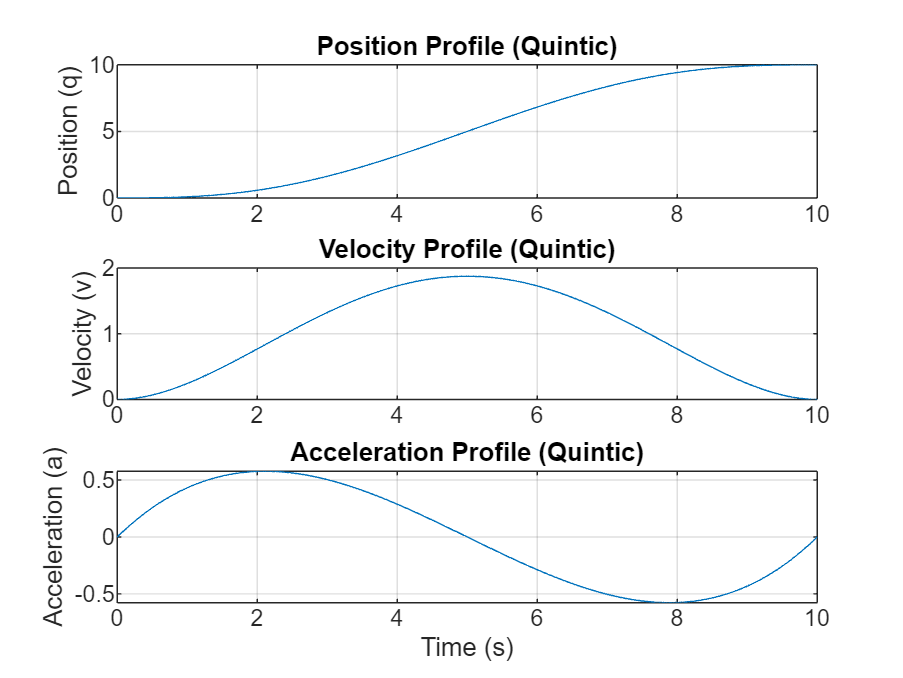

% Plot the trajectory
figure;
subplot(3,1,1);
plot(t, q);
title('Position Profile (Quintic)');
ylabel('Position (q)');
grid on;

subplot(3,1,2);
plot(t, v);
title('Velocity Profile (Quintic)');
ylabel('Velocity (v)');
grid on;

subplot(3,1,3);
plot(t, a);
title('Acceleration Profile (Quintic)');
ylabel('Acceleration (a)');
xlabel('Time (s)');
grid on;